# **Ejercicio 4**

## Problema T6_7.4. Integración de Simpson 3/8

clear, clc % Limpieza del entorno de trabajo

a) Escribe una función de MATLAB que utilice el método compuesto de  Simpson 3/8 para la integración de una función $f\left(x\right)$ que está dada en forma  anónima (f = @(x)).

- Véase Simpson38.m

b) Utiliza Simpson38 para resolver el siguiente problema: 

(Todos los cálculos se deben realizar con un error menor a ${10}^{-5}$)

Er = 1e-5;

En el diseño de tuberías subterráneas, es necesario estimar la temperatura del  suelo. La temperatura del suelo a distintas profundidades puede estimarse  modelando el suelo como un sólido semi-infinito inicialmente a temperatura  constante.

La temperatura a la profundidad, x, y al tiempo,  t, puede calcularse a partir de la expresión:

donde $T_s$ es la temperatura de la superficie, $T_i$ es  la temperatura inicial del suelo y  $\alpha$= 0.138$\cdot {10}^{-6}$ es la difusión térmica del  suelo. Suponiendo que $T_s$ = −15ºC y $T_i$ = 12ºC

alpha = 0.138*10^-6;
Ts = -15;
Ti = 12;
y = @(u) exp(-u.^2);

b.1) Representa gráficamente la temperatura en función del tiempo a una  profundidad de x = 0,5 m durante 40 días. Utiliza incrementos de 1 día comenzando por un valor de t próximo a cero (pero que no sea cero).

Despejando la ecuación anterior tenemos que:


$$T\left(x,\;t\right)=\left(T_i -T_s \right)\frac{2}{\sqrt{\pi }}\int_0^{\frac{x}{2\sqrt{\alpha \;t}}} e^{{-u}^2 } \textrm{du}+T_s$$


x = 0.5;
t = 0.001:1:40;
n = length(t);
I = zeros(n,1);
I_matlab = zeros(n,1);
syms u
z = exp(-u.^2)

$$z = {\mathrm{e}}^{-u^{2}}$$

for i=1:n
    I(i) = Simpson38(y, 0, x/(2*sqrt(alpha*t(i))), Er);
    I_matlab(i) = int(z, 0, x/(2*sqrt(alpha*t(i))));
end
T = (Ti - Ts) * (2/sqrt(pi)) * I  + Ts

T =    12.0000
   12.0000
   12.0000
   12.0000
   12.0000
   12.0000
   12.0000
   12.0000
   12.0000
   12.0000


T_matlab = (Ti - Ts) * (2/sqrt(pi)) * I_matlab  + Ts

T_matlab =     12
    12
    12
    12
    12
    12
    12
    12
    12
    12


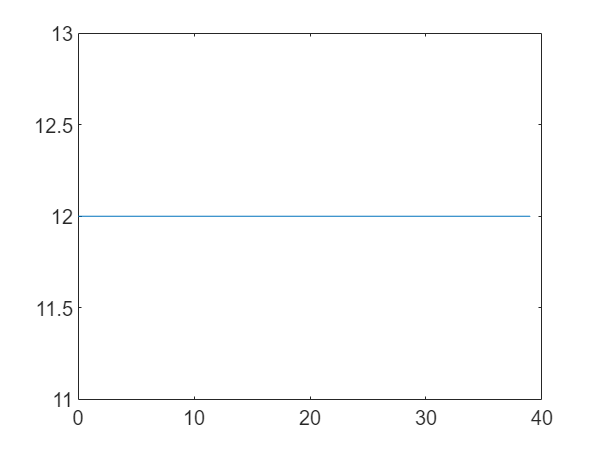


plot(t,T_matlab)

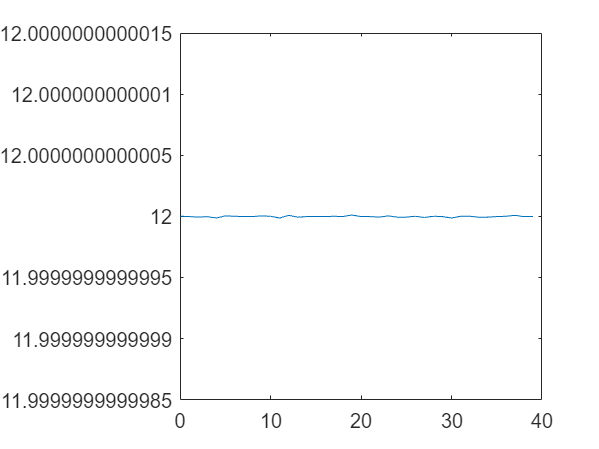

T alf: 12.0000000000

T matlab: 12.0000000000

plot(t, T)

b.2) Calcula la temperatura a una profundidad x = 1m después de 30 días  (t = 2,592$\cdot {10}^6$)

x = 1;
t = 2.592*10^6;
I2 = Simpson38(y, 0, x/(2*sqrt(alpha*t)), Er);
T = (Ti - Ts) * (2/sqrt(pi)) * I2  + Ts

T = 5.5987